# Small-Signal Stability Analysis of an Essential System

This demo shows a small-signal stability analysis of an essential system using the MTI Toolbox. The essential system consists of a grid-following converter, a grid-forming converter, and a load, all of them connected to a Thévenin-equivalent grid. 

It initializes operating points from the nonlinear time-invariant model in Simulink. Then it builds an implicit multilinear time-invariant model of the system and computes its Jacobian to form the linear descriptor state-space model. Stability is then assessed by finding the generalized eignevalues of the linear descriptor state-space model. Comparisons between the simulated response behavior of the nonlinear time-invariant model, the implicit multilinear time-invariant model, and the linear descriptor state-space model are made. 

19.08.2025, Christoph Kaufmann

clear; clc;

## Case Study & Parametrization

### Choose Case Study

In the following script, the demo automates the workflow for small-signal stability analysis running through model set up, simulation, linearization and eigenvalue analysis. Since each step is modular and can be adapted for different scenarios we begin by 'selecting' the simulation and analysis options to be executed. 

SimulationSetup.model='GFM_GFL'; % 'GFL','GFM','GFM_GFL'
SimulationSetup.JacobianCalculation='no'; % 'yes','no'
SimulationSetup.caseStudy='VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep055'; % check selectionCaseStudy
            % VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep055
            % VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep
SimulationSetup.Solver.MaxStep=1e-4;
SimulationSetup.Solver.RelTol=1e-4;
SimulationSetup.Solver.MTI='dmsim'; 
SimulationSetup.Descriptor.simulate='no'; % 'yes', 'no'
SimulationSetup.Descriptor.SimulationTime=0.01;%0.01;
SimulationSetup.totalNumberOfSimulationScenarios=1;
SimulationSetup.eigenvalueAnalysis='trajectory';% 'single', 'trajectory'
SimulationSetup.ModelABCcoordinates.simulate='no'; % 'yes', 'no'
SimulationSetup.ComputationalAssessment='no'; % 'yes','no'


### Model Topology: GFM_GFL

The selected model is GFM_GFL, which consists of a grid-following (GFL) converter, a grid-forming (GFM) converter, and a load, all of them connected to a Thévenin-equivalent grid as depicted in the figure below. 

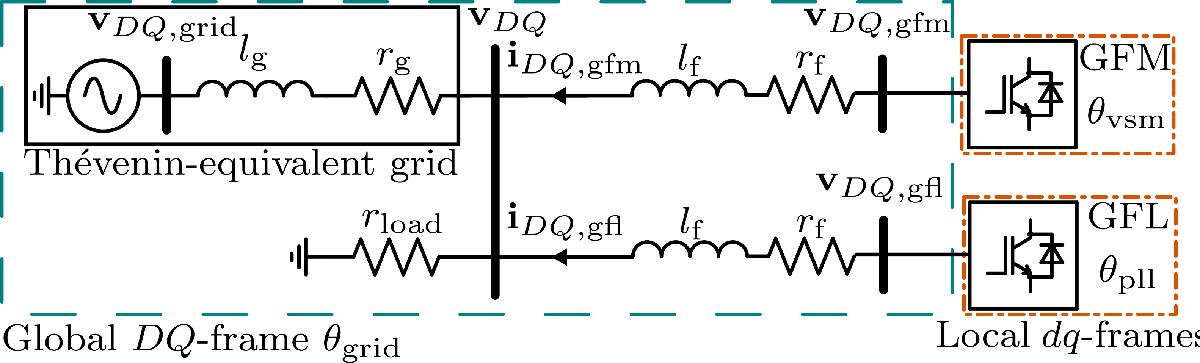

Figure 1. Scheme of the essential system in the global frame $\theta_{\textrm{grid}}$ (dashed line), and the local frames of the converters (dashed-dotted line) [1]

### Parametrize Model

In this step all the fundamental electrical parameters and controller settings are loaded, e.g., base voltage and  current, short-circuit ratio and the resulting grid impedance, converter filter and tuning, etc. These parameters will be used when the model will be built at a later stage. 

run parametrization.m;

### Load Case Study

The time events for loads, grid disturbances and converter references( e.g. step changes and activation times) are set here. As well as the simulation and analysis time points. 

run selectionCaseStudy;

For case study *"VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep055" *selected above, the simulation is set to run for 3 s with each bus initially set to see a steady-state load equivalent to 50 % of the load. Then at 2 s a voltage step is introdued, and at  2.5 s there is a step-up in the load. Note the naming convention is indicative of the case's behavior:

## Build Multilinear Model & Compute Jacobian

Here the implicit multilinear time-invariant (iMTI) model for the selected scenario is constructed and stored as a canonical polyadic norm-1 normalized (CPN1) decomposed tensor, which allows for efficient linearization [1].

The scenario can be modified or more converters added by updating the connection logic in 'buildMTImodel.m' 

disp('------- Building MTI model.------- ')

------- Building MTI model.------- 


run buildMTImodel;

Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 6 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 4 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Info: Multiple Inputs have the same name. They will be converted into one similar input!
Reduced by 15 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 2 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 12 column(s) and 0 equation(s) with trivial Reduction due to duplications.
Reduced by 4 column(s) and 0 equation(s) with trivial Reduc

The Jacobian is then computed for the iMTI model, where the chain rule needs to be considered due to a nonlinear change of variables during the model construction, see [1] for more details. 

if strcmp(SimulationSetup.JacobianCalculation,'yes')
    disp('------- Computing Jacobian handle of the MTI model.------- ')
    tic 
    run iMTImodelJacobianChainRule;
    multilinearResults.JacobianTime=toc;
end


From the Jacobian, a  linear descriptor state-space (LDSS) model is constructed, which approximates the iMTI model for small disturbances around the provided equilibrium point, see [1] for more details. 

## Simulation

### Simulate Nonlinear Model in dq-coordinates

A nonlinear time-invariant (NTI) model of the power system in Simulink is run to obtain time-series data for all relevant signals. It is used to obtain the system's operating points, for providing initialization data for the iMTI model.

disp('------- Running Simulink model to obtain operating points for initialization. ------ ')

------- Running Simulink model to obtain operating points for initialization. ------ 


run simulationSimulinkModel.m;

### Simulate Multilinear & Linear Descriptor Model

A time-domain simulation of the iMTI model using the MTI Toolbox *dmsim* function, and the LDSS model if selected, are performed. Both simulations use initial conditions and input signals obtained from the NTI model.  A plot comparisons of the time-domain simulation of the NTI and iMTI models are output for both the GFM and GFL converters. The active and reactive power, $p$ and $q$ , respectively, and the Euclidean norm of the voltage and the current, are plotted in per-unit (p.u.), and the estimated frequency of the PLL in Hz, as well as the angle difference $\delta$ between local and global frame, measured in Degrees, are given.

disp(['------- Simulation of the MTI model for the case study :',SimulationSetup.caseStudy])

------- Simulation of the MTI model for the case study :VoltageStep_SCR5_XR10_equalLoadDistribution_Rstep055


------- Simulation of the MTI model for the case study :dmsim
All initial state values are obtained.


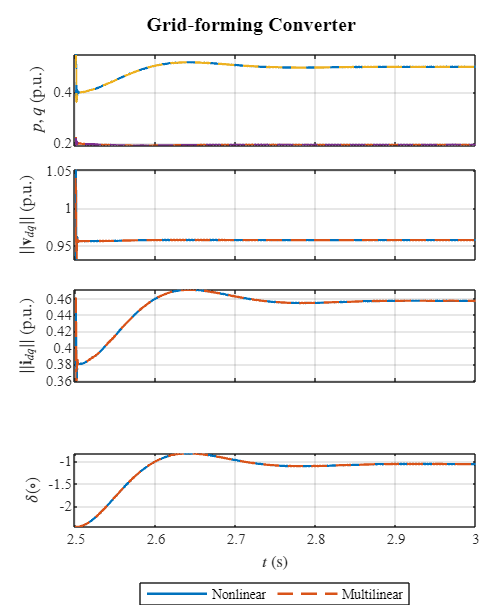

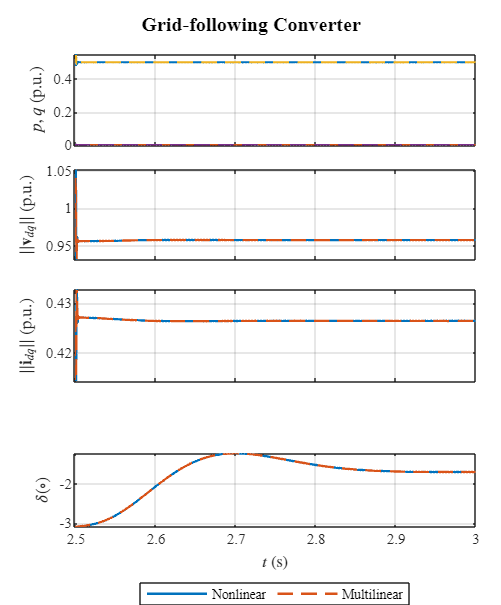

Finished 3 simulation ouf of 1 requiring 21.0669 s for computation.



run simulationMTImodel;

### Simulate Nonlinear Model in abc-coordinates

The following allows for a comparison of the model dq-coordinates with the original NTI model in abc-coordinates.

if strcmp(SimulationSetup.model,'GFM_GFL') && strcmp(SimulationSetup.ModelABCcoordinates.simulate,'yes')
   run simulationModelABCcoordinates.m;
   run plottingComparisonABCs.m;
end

## Small-signal Analysis by Assessing  the (Generalized) Eigenvalues

The generalized eigenvalues of the LDSS model are compared with the eigenvalues of the linear state-space  (LSS) model of the linearized NTI model to assess the stability of the equilibrium point. The LSS is obtained using the *linearize* command of the Control System Toolbox. 

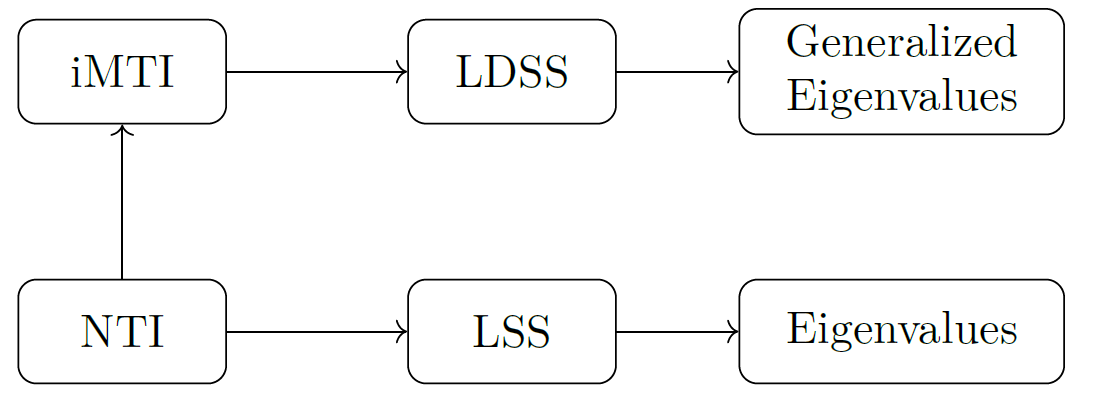

Figure 2. Comparison of the small-signal stability analysis methods using iMTI modeling and NTI modeling

disp(['------- Computing eigenvalues: ',SimulationSetup.eigenvalueAnalysis,' ----------------'])

------- Computing eigenvalues: trajectory ----------------


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


All initial state values are obtained.
All initial state values are obtained.


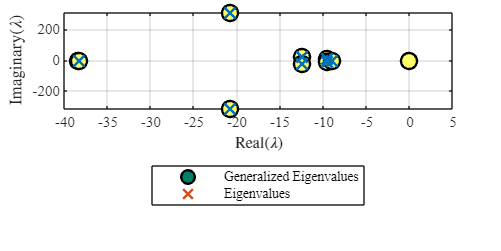


run eigenvalueComputation;

## Computational Aspects 

Here one can optionally assess and compare the computational performance of the main steps in the workflow.

It collects and displays the time taken for:

- Simulating the NTI model, linearizing and computing eigenvalues using functions from the Control Systems Toolbox 

- Simulating the iMTI model, linearizing it and computing the generalized eigenvalue using functions from the MTI Toolbox 

if strcmp(SimulationSetup.ComputationalAssessment,'yes')
    disp('------- Computational assessment  ----------------');
    run computationalAssessment.m;
end

## References

[1] C. Kaufmann, G. Pangalos, G. Lichtenberg, O. Gomis-Bellmunt,  "Small-Signal Stability Analysis of Power Systems by Implicit Multilinear Models", preprint available on arXiv, 2025. 